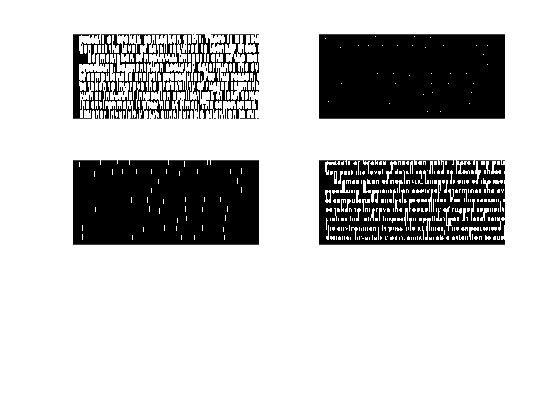

%读取图像
fig = imread("Fig1.tif");
%figure;
%imshow(fig);

%图像二值化
fig_2 = logical(fig);

%设置膨胀结构元素
E(1:51,1) = 1;

%膨胀操作
my_d = My_dilation(fig_2,E);

%展示膨胀后结果
subplot(3,2,1);imshow(my_d);title("膨胀");axis on;

%腐蚀操作

my_e = My_erosion(fig,E);
%展示腐蚀后结果
subplot(3,2,2);imshow(my_e);title("腐蚀");axis on;
% 先腐蚀后膨胀 => 开启
my_ed = My_dilation(logical(My_erosion(fig,E)),E);
subplot(3,2,3);imshow(my_ed);title("开启");axis on;
% 先膨胀后腐蚀 => 闭合
my_de = My_erosion(logical(My_dilation(fig,E)),E);
subplot(3,2,4);imshow(my_de);title("闭合");axis on;